# 实验一： 计算机控制系统性能分析

考虑如图1所示的计算机控制系统

Ts=0.5;

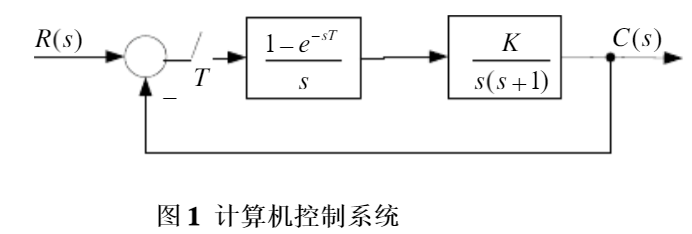

## 一、系统稳定性分析

### 1.1 离散系统的稳定性分析

    离散系统稳定的充要条件为，系统的特征根全部位于z平面的单位圆中，只要有一个根位于单位圆外，系统就不稳定。（教材P104）观察下图并使用*rlocfind(sysd)*可以寻找到令系统稳定的K的取值范围大致为为**:0<K<4.3581**。

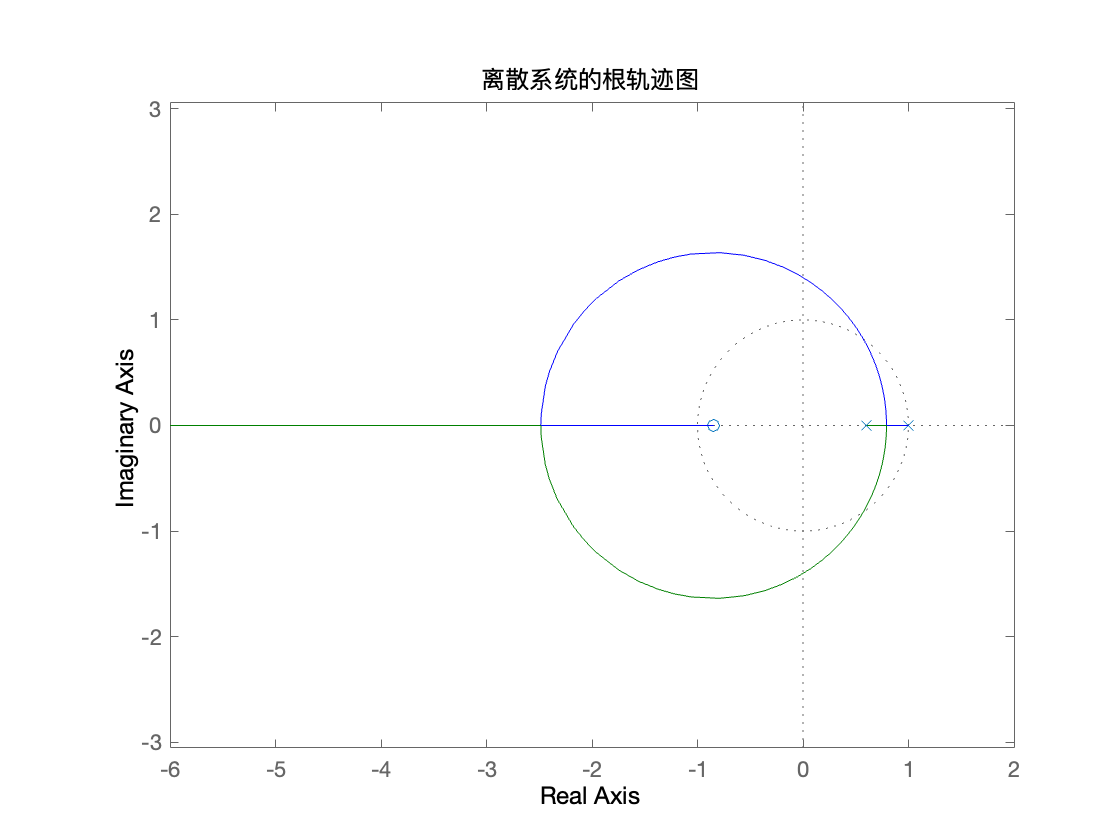

%增益为1的开环传递函数
num=1;
den=conv([1 0],[1 1]);
sysc=tf(num,den);
%ZOH离散化
sysd=c2d(sysc,Ts,'zoh');
figure();
rlocus(sysd)
title("离散系统的根轨迹图")
axis equal

### 1.2 连续系统稳定性

`    连续系统稳定取决于闭环系统的特征根在s平面上的位置，若特征根全在s平面左半平面则系统稳定，只要有一个根在s平面右半平面或虚轴上，则系统不稳定。`从下图根轨迹图中可以看出，系统根轨迹位于左半平面，无论K(K>0)的取值如何，系统恒定处于稳定状态。

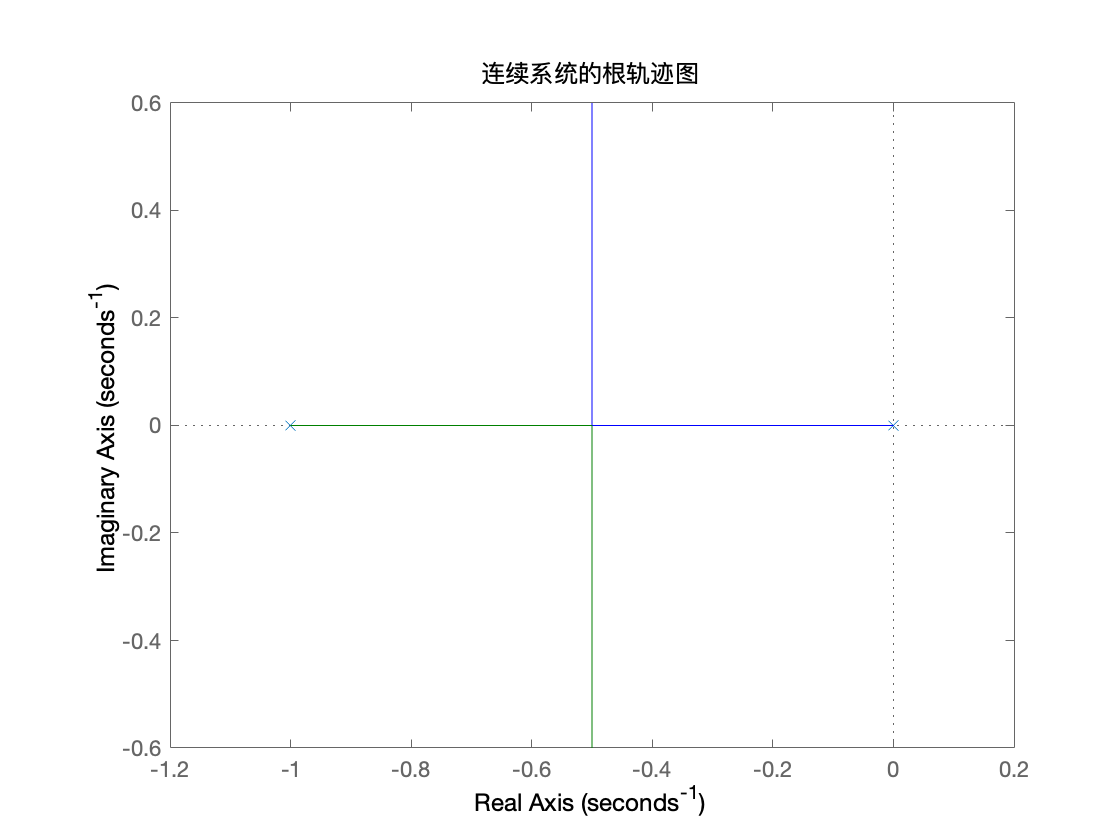

figure();
rlocus(sysc)
title("连续系统的根轨迹图")

### 1.3 分析导致上述两种情况下K取值范围差异的原因

    在本例中，连续系统的稳定性比离散系统好，增大K值会使得离散系统变得不稳定。`加入采样开关以后，采样周期越大，离散系统系统稳定性越差，能使系统稳定的`K`的范围越小。`

## 二、时域特性分析

K=2;

### 2.1 连续系统阶跃响应信号及性能指标

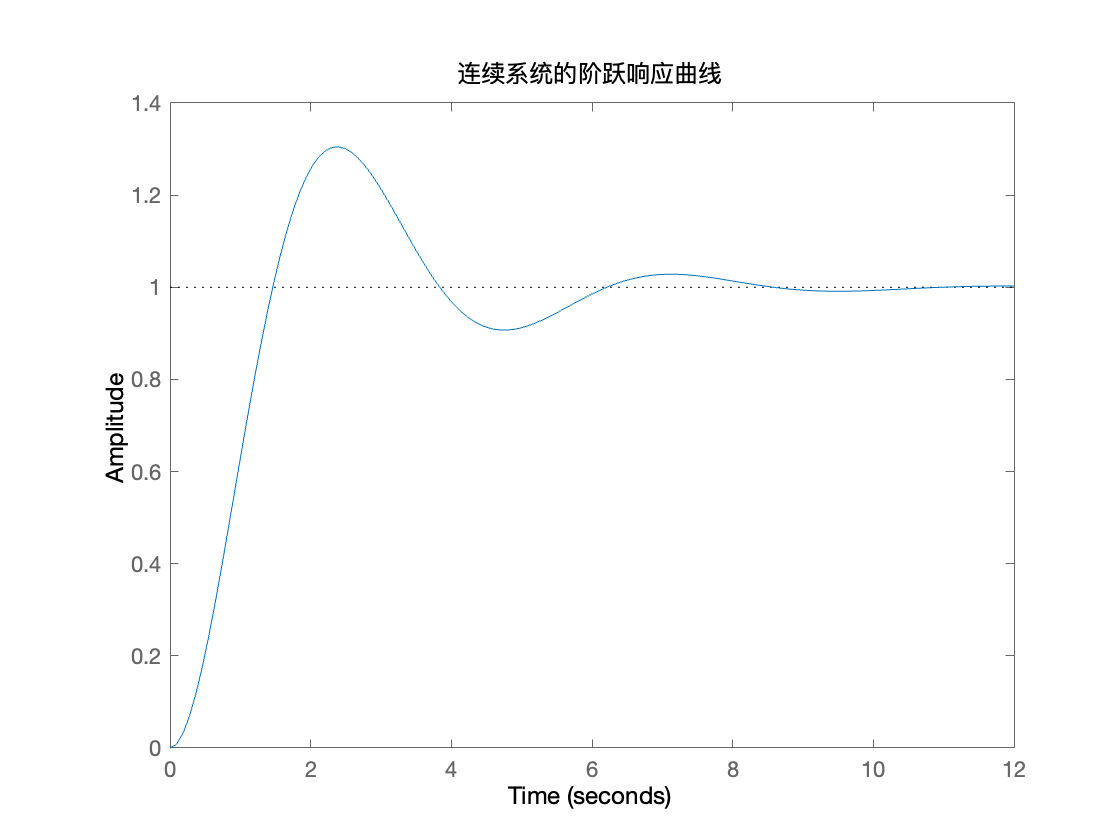

Phic=feedback(K*sysc,1);
infoc=stepinfo(Phic);%计算性能指标
stepplot(Phic);
title("连续系统的阶跃响应曲线")

### 2.2 离散化系统阶跃响应波形及性能指标

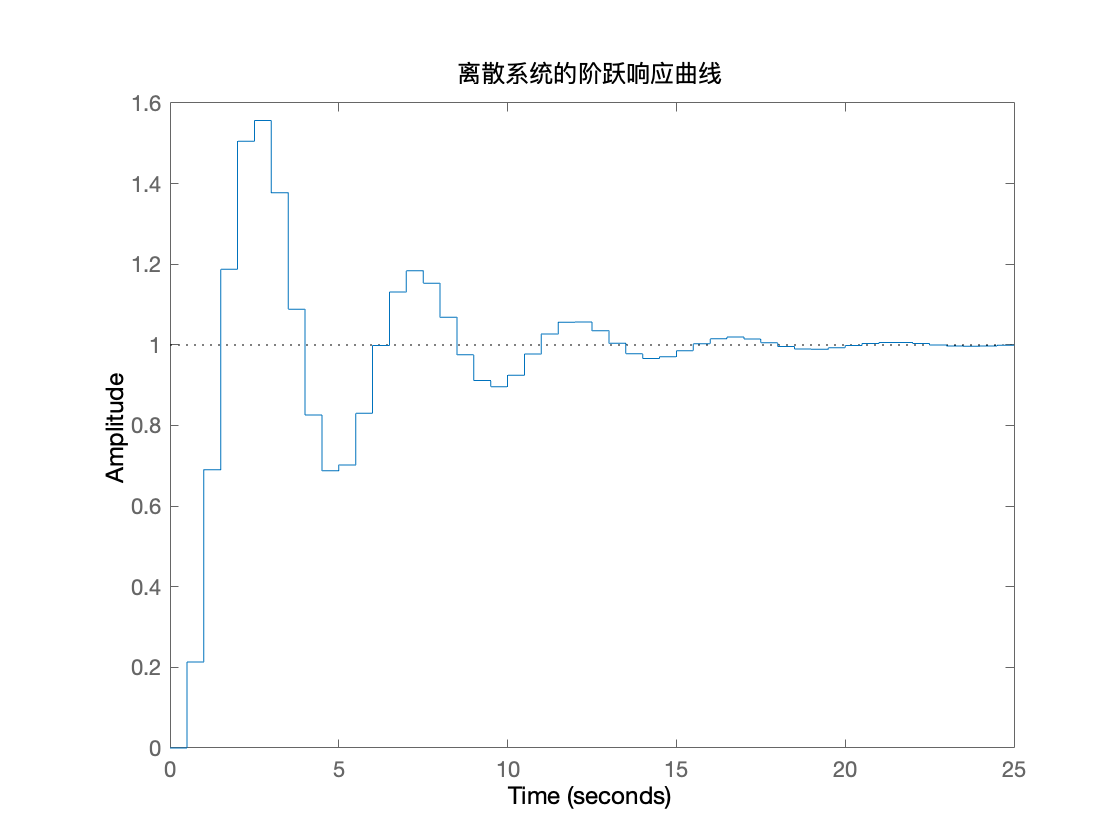

Phid=feedback(K*sysd,1);
infod=stepinfo(Phid);%计算性能指标
stepplot(Phid);
title("离散系统的阶跃响应曲线")

### 2.3 离散系统与连续系统动态性能及性能指标之间的比较

`    由于采样开关和零阶保持器的存在，使得离散系统的时域响应与连续系统相比发生变化，稳定性相对降低，动态性能相对变差。`

label={'离散系统','连续系统'};
s=[infod,infoc];%合并数据，进行比较
info=struct2table(orderfields(s,[1,5,2,8,3,4,7,6]),'RowNames',label)

info = 2×8 table
               RiseTime    Overshoot    SettlingTime    PeakTime    SettlingMin    SettlingMax     Peak     Undershoot
               ________    _________    ____________    ________    ___________    ___________    ______    __________

    离散系统          1      55.642            15            2.5       0.68794        1.5564       1.5564        0     
    连续系统    0.98874      30.489         7.742         2.3947       0.90711        1.3049       1.3049        0     


绘制两个响应曲线如下

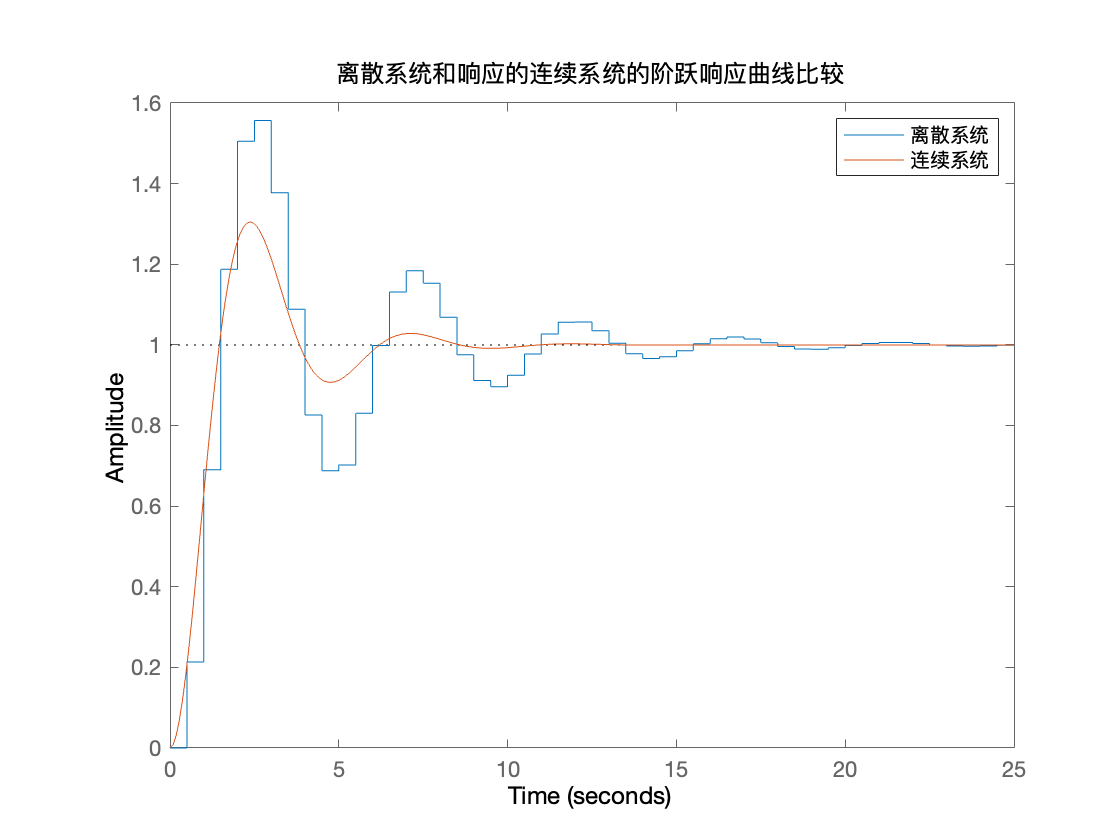

stepplot(Phid,Phic);
legend(label);
title("离散系统和响应的连续系统的阶跃响应曲线比较")

## 三、频域特性

### 3.1 连续系统频率特性

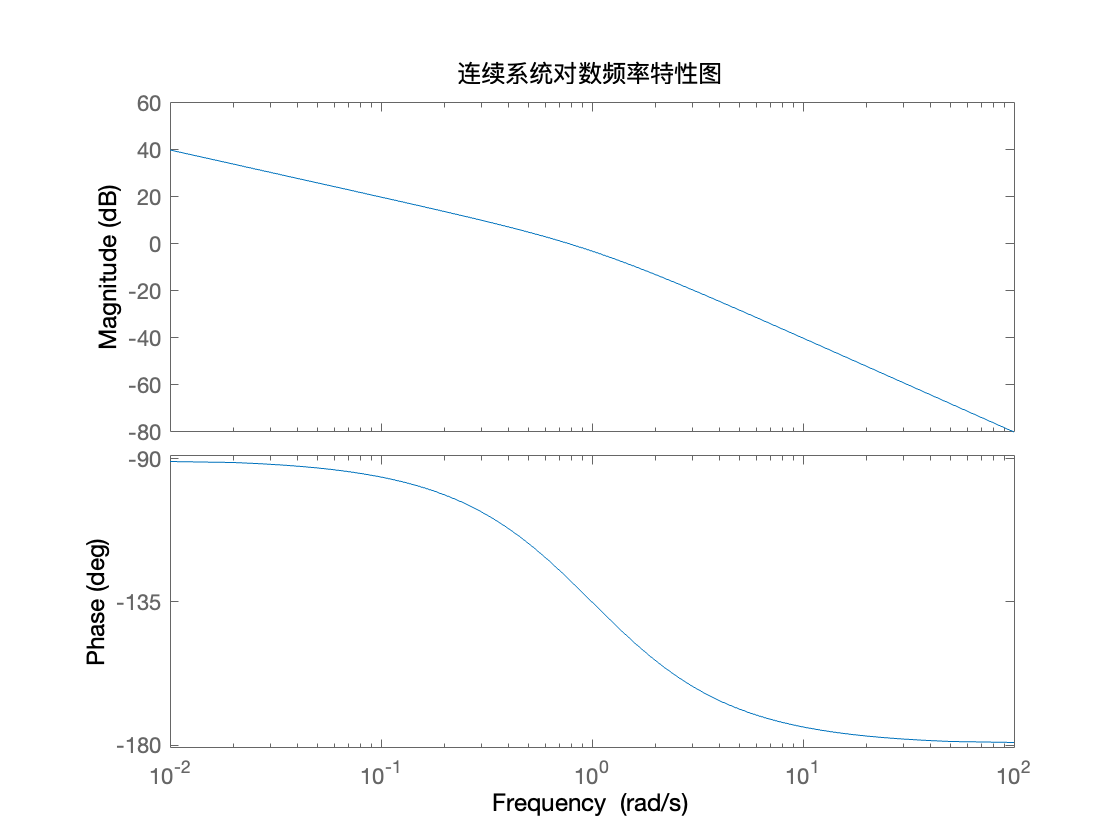

figure();
bodeplot(sysc);
title("连续系统对数频率特性图");

### 3.2 离散系统频率特性

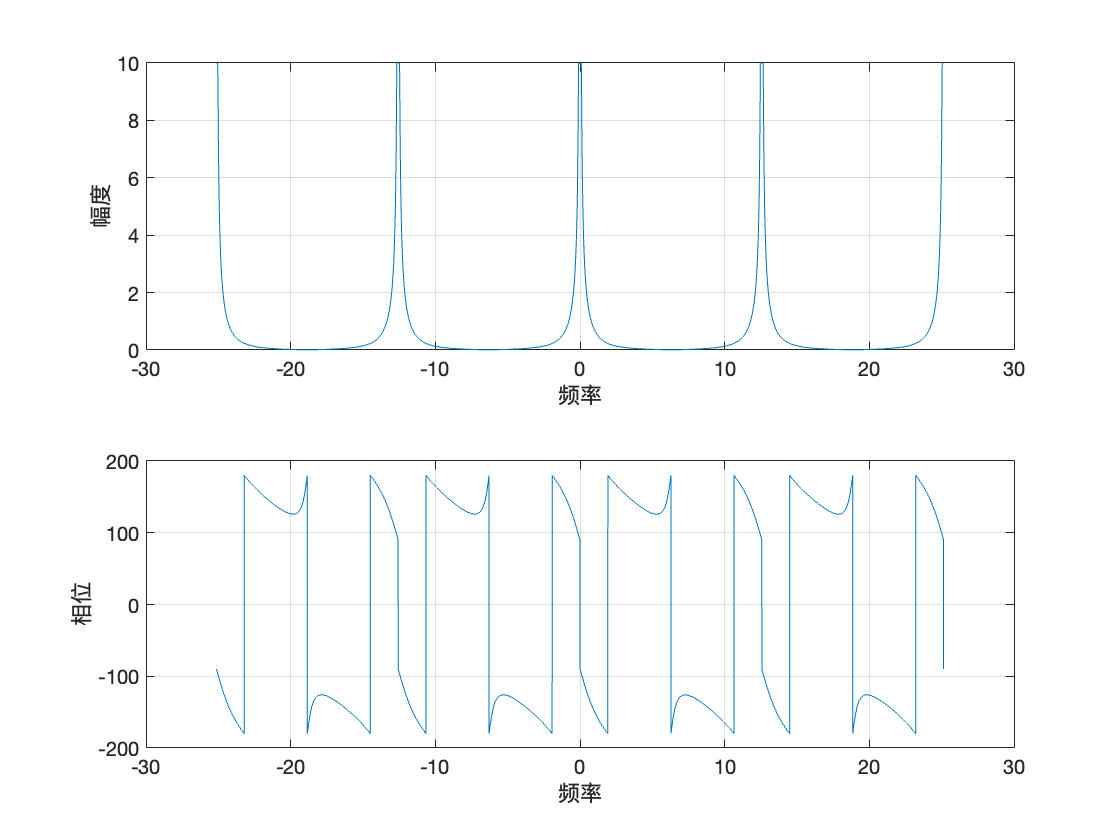

figure();
subtitle('离散系统的频率特性曲线')
ws=2*pi/Ts;%采样频率
w=linspace(-2*ws,2*ws,40000);
[magd,phased,woutd] = bode(sysd,w);
%相位处理，将相位限制在-180到180度之间
phased = mod(phased+180,360)-180;
%幅值处理，防止数值过大
magd=(magd<10).*magd+(magd>=10)*10;
%绘制幅频特性曲线
subplot(2,1,1);
plot(woutd,magd(:));
grid on;
xlabel('频率');ylabel('幅度');
%绘制相频特性曲线
subplot(2,1,2);
plot(woutd,phased(:));
grid on;
xlabel('频率');ylabel('相位');

### 3.3 考虑采样保持前后系统频率特性比较

   从频率响应曲线中，可以看出离散系统的频率特性的特点：

- 以采样频率为周期的周期函数，连续系统无该特性

- 其幅频特性为偶函数，相频特性为奇函数，连续系统也有该特性

- 离散系统仅仅在较小的采样周期或低频段与连续系统频率特性相近

- 离散系统高频时会出现多个峰值

- 离散系统会出现正相位

由于离散环节频率特性$G(e^{j\omega T})$不是$\omega
$的有理分式函数，在绘制对数频率特性时，不能像连续系统那样使用渐进对数频率特性。但由于对数很坐标能压缩频率区间、简化运算等优点，因此，在离散系统频域分析时还常常使用对数频率特性。

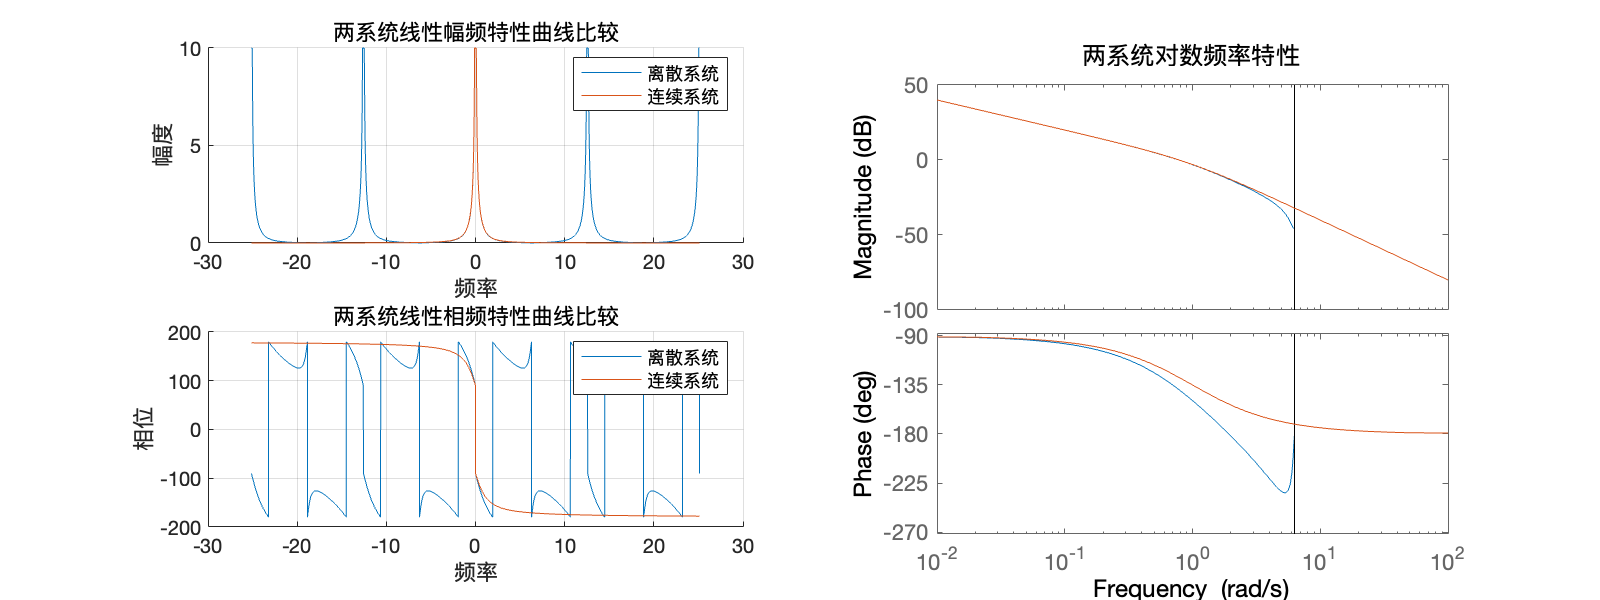

figure('position',[0,0,800,300]);
ws=2*pi/Ts;%采样频率
w=linspace(-2*ws,2*ws,40000);
[magd,phased,woutd] = bode(sysd,w);
[magc,phasec,woutc] = bode(sysc,w);
%相位处理，将相位限制在-180到180度之间
phased = mod(phased+180,360)-180;
phasec = mod(phasec+180,360)-180;
%幅值处理，防止数值过大
magd=(magd<10).*magd+(magd>=10)*10;
magc=(magc<10).*magc+(magc>=10)*10;
%绘制幅频特性曲线
subplot(2,2,1);hold on;
plot(woutd,magd(:));
plot(woutc,magc(:));
legend(label);hold off;
title('两系统线性幅频特性曲线比较')
xlabel('频率')
ylabel('幅度')
grid on;
%绘制相频特性曲线
subplot(2,2,3);hold on;
plot(woutd,phased(:));
plot(woutc,phasec(:));
legend(label);hold off;
title('两系统线性相频特性曲线比较')
xlabel('频率')
ylabel('相位')
grid on;
subplot(2,2,[2,4]);
bode(sysd,sysc);
title('两系统对数频率特性')

## 附：关于MATLAB离散系统波特图中高频部分的分析

    使用MATLAB绘制离散系统频率特性时（如下图的左图），MATLAB省略了离散系统传递函数频率大于$\frac{\omega_s}{2$的部分，由上节可知，此时频率响应应为上一周期的不断重复。我们可以通过指定w参数，来设置需要绘制波特图的频率范围（如下右图），乍一看离散系统的频率特性似乎不像是周期函数，但是考虑到如下因素可以发现频率特性仍然是周期函数。

- 横坐标是对数坐标系，所以有一些变形是正常的

- 对于相位，如果将相位限制到$\pm 180  deg
$之间，那么显然将会呈现周期函数特性

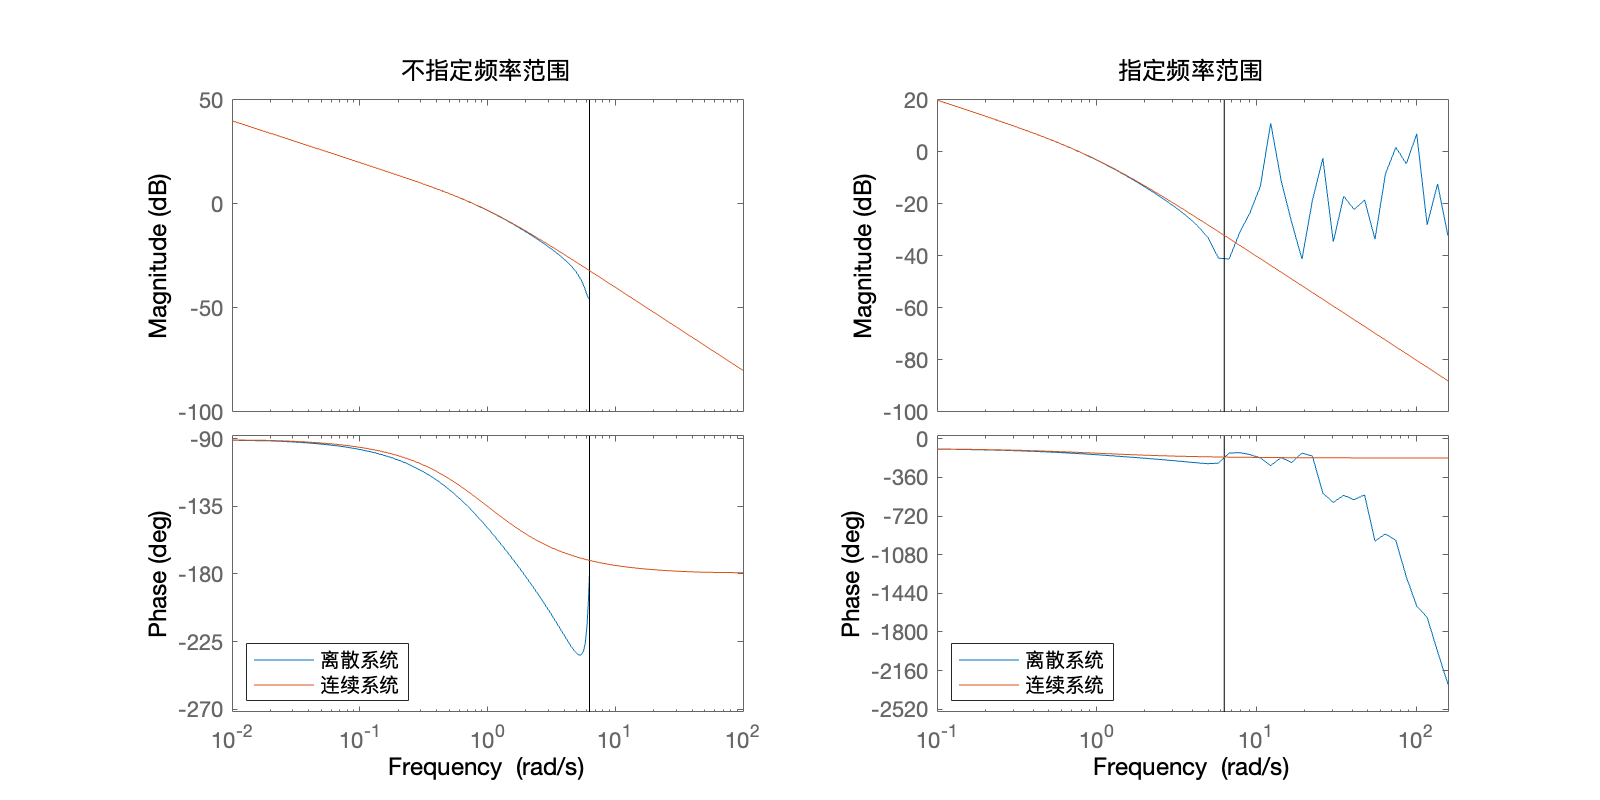

figure('Position',[0,0,800,400]);
subplot(1,2,1);
bode(sysd,sysc)
legend(label,"Location","southwest");
title("不指定频率范围")
subplot(1,2,2);
w=logspace(-1,2.2);
bode(sysd,sysc,w);
legend(label,"Location","southwest");
title('指定频率范围')

## 附： 差拍现象

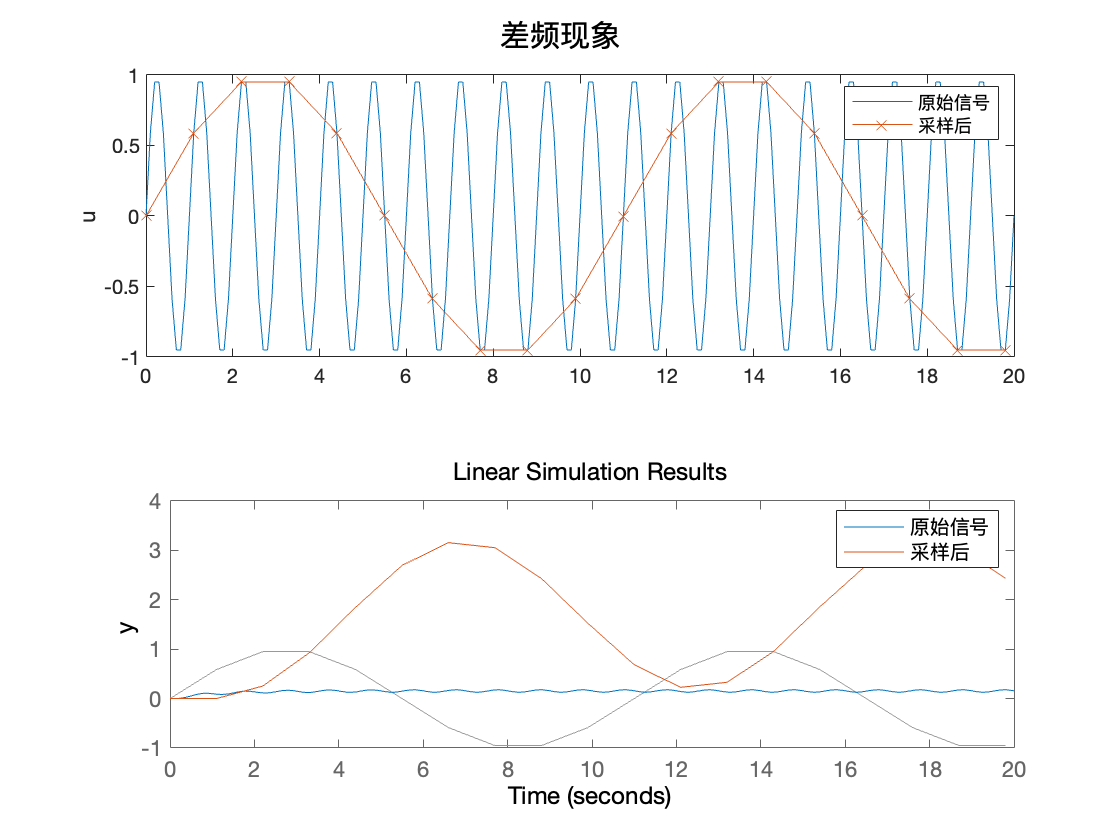

%产生正弦波
tau=1;
Tf=20;
[u,t]=gensig('sine',tau,Tf,0.1);
[u2,t2]=gensig('sine',tau,Tf,1.1);
N=length(u);
figure();
sgtitle('差频现象');
subplot(2,1,1);
plot(t,u,t2,u2,'x-');
legend('原始信号','采样后');
ylabel('u');
subplot(2,1,2);
hold on;
lsimplot(sysc,u,t,0,'zoh');
lsimplot(sysc,u2,t2,0,'zoh');
legend('原始信号','采样后');
ylabel('y')
hold off;